% General motion transformation by Kai De La Cruz - 1/25/25
%   PURPOSE:
%   Capable of three consecutive transforms from frame B (noa) and finds
%   new representation in frame B. 
%
%   Furthermore, translates representation in noa frame to the fixed
%       reference frame if frame B was originally attached at orgin and parallel.
%
%   HOW TO USE:
%   1) Input original point
%   2) Input each consecutive transform one at a time (the remaining
%           transforms equal to identity matrix)
%   3) After each transform, look at 3D plot and decide what rotation makes
%           sense next.  
%   4) Confirm frame B vector and fixed reference frame vector end at same
%           transformed point. 
       


## INPUTS


% original point in frame B 
xxx = 2;
yyy = -1;
zzz = 3;

x = -2;
y = 4;
z = 1;

% Define the rotation angles (in degrees)
theta_x = 0; % Rotation about the X-axis
theta_y = 90; % Rotation about the Y-axis
theta_z = 0; % Rotation about the Z-axis


num_steps = 20;

dx = x/num_steps;
dy = y/num_steps;
dz = z/num_steps;

dtx = theta_x/num_steps;
dty = theta_y/num_steps;
dtz = theta_z/num_steps;

function T = T_translation(dx,dy,dz)
    T = [1 0 0 dx; 
            0 1 0 dy; 
            0 0 1 dz; 
            0 0 0 1];
end

function T = rot(axis,angle)
    if axis == "x"
        T = [1 0 0 0; 
             0 cosd(angle) -sind(angle) 0; 
             0 sind(angle) cosd(angle) 0; 
             0 0 0 1];                              % or n-axis
    elseif axis == "y"
        T = [cosd(angle) 0 sind(angle) 0; 
             0 1 0 0; 
             -sind(angle) 0 cosd(angle) 0; 
             0 0 0 1];                              % or o-axis
    else
        T = [cosd(angle) -sind(angle) 0 0; 
             sind(angle) cosd(angle) 0 0; 
             0 0 1 0; 
             0 0 0 1];                              % or a-axis
    end

end

figure;

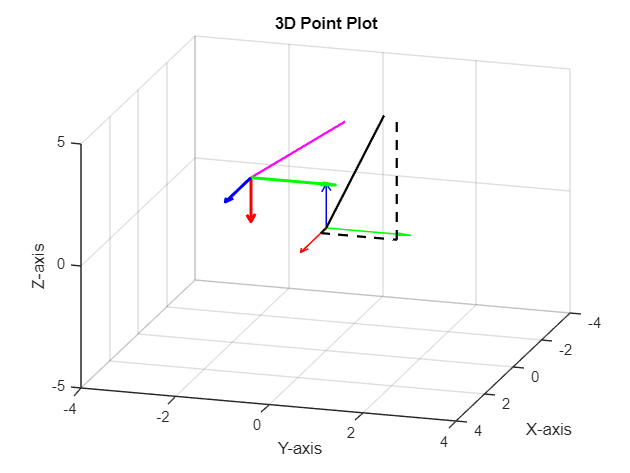



% common rotation transforms
for i=1:1
for k = 1:num_steps

    x = dx*k;
    y = dy*k;
    z = dz*k;

    theta_x = dtx*k;
    theta_y = dty*k;
    theta_z = dtz*k;

    identity = [1 0 0 0; 
                0 1 0 0; 
                0 0 1 0; 
                0 0 0 1];
    
   % 3 CONSECTUTIVE TRANSFORMS CALC
    
    P_b =  [-1 0 0 xxx; 
            0 1 0 yyy; 
            0 0 1 zzz; 
            0 0 0 1];       % original point in frame B, at [2,3,4] transposed
    
    T_01 = T_translation(x,y,z);      % first transform, rot(y,90)
    
    T_12 = rot("z",45);       % second transform. xyz
    
    T_23 = rot("x",30);       % third transform, noa
    
    
    % noa frame you POST-multiply, xyz you PRE-multiply
    P_b_new = T_01*T_12*P_b*T_23 ;   % new representation in frame B
     % TRANSLATE FROM FRAME NOA TO FIXED REFERENCE FRAME.
    
    T_xyz_noa = P_b_new;
    
    P_noa = [P_b(1,4);
             P_b(2,4);
             P_b(3,4);
             P_b(4,4);];    % original point in noa frame
    P_xyz = T_xyz_noa*P_noa;
    % GRAPHICAL REPRESENTATION
   
    
    % point in XYZ frame
    xx = P_xyz(1,1);
    yy = P_xyz(2,1);
    zz = P_xyz(3,1);
    
    % Convert angles to radians
    theta_x = deg2rad(theta_x);
    theta_y = deg2rad(theta_y);
    theta_z = deg2rad(theta_z);
    
    % Define the rotation matrices
    Rx = [1, 0, 0;
          0, cos(theta_x), -sin(theta_x);
          0, sin(theta_x), cos(theta_x)];
      
    Ry = [cos(theta_y), 0, sin(theta_y);
          0, 1, 0;
         -sin(theta_y), 0, cos(theta_y)];
     
    Rz = [cos(theta_z), -sin(theta_z), 0;
          sin(theta_z), cos(theta_z), 0;
          0, 0, 1];
    
    % Combine the rotations into a single matrix (Z -> Y -> X order)
    R = Rz * Ry * Rx;
    
    % Define the original coordinate system axes with adjustable lengths
    axis_length = 2; % Length of the axes
    x_axis = axis_length * [1, 0, 0];  % X-axis
    y_axis = axis_length * [0, 1, 0];  % Y-axis
    z_axis = axis_length * [0, 0, 1];  % Z-axis
    
    % Apply the rotation matrix to each axis
    x_rotated = (R * x_axis')'; % Rotated X-axis
    y_rotated = (R * y_axis')'; % Rotated Y-axis
    z_rotated = (R * z_axis')'; % Rotated Z-axis
    
    
    plot3(xx, yy, zz, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Plot the point
    hold on;
    grid on;
    view([160.69 40.76]);
    xlim([-4 4]);
    ylim([-4 4]);
    zlim([-5 5]);
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title('3D Point Plot');
    
    grid on;
    % Plot lines from the origin to the point
    plot3([0, xx], [0, 0], [0, 0], 'k--', 'LineWidth', 1.5); % X-line
    plot3([xx, xx], [0, yy], [0, 0], 'k--', 'LineWidth', 1.5); % Y-line
    plot3([xx, xx], [yy, yy], [0, zz], 'k--', 'LineWidth', 1.5); % Z-line
    
    % Add an arrow from the origin to the point
    plot3([0, xx], [0, yy], [0, zz], 'k-', 'LineWidth', 1.5); % Global origin to point
   
    % Add an arrow from the noa frame origin to the point
    plot3([P_noa(1), xx], [P_noa(2), yy], [P_noa(3), zz], 'm-', 'LineWidth', 1.5); % NOA origin to point
    
    
    % Plot the original coordinate system
    quiver3(0, 0, 0, x_axis(1), x_axis(2), x_axis(3), 'r', 'LineWidth', 1, 'MaxHeadSize', 0.5); % Original X-axis
    quiver3(0, 0, 0, y_axis(1), y_axis(2), y_axis(3), 'g', 'LineWidth', 1, 'MaxHeadSize', 0.5); % Original Y-axis
    quiver3(0, 0, 0, z_axis(1), z_axis(2), z_axis(3), 'b', 'LineWidth', 1, 'MaxHeadSize', 0.5); % Original Z-axis
    
    % Plot the rotated coordinate system
    quiver3(xxx, yyy, zzz, x_rotated(1), x_rotated(2), x_rotated(3), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5); % Rotated X-axis
    quiver3(xxx, yyy, zzz, y_rotated(1), y_rotated(2), y_rotated(3), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5); % Rotated Y-axis
    quiver3(xxx, yyy, zzz, z_rotated(1), z_rotated(2), z_rotated(3), 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5); % Rotated Z-axis
    
    
    % Add labels and grid
    % xlabel('X-axis');
    % ylabel('Y-axis');
    % zlabel('Z-axis');
    % title('3D Point Plot');
    % grid on;
    
    % Set axis limits for better visualization (optional)
    %axis([-10 10 -10 10 -10 10]); % Adjust limits as needed
    
    % Update the legend with the point's coordinates
    % legend(sprintf('Point (%.2f, %.2f, %.2f)', xx, yy, zz))
     % Release the figure
    % drawnow
    pause(0.1);
    hold off
end
end